- Re-analyze consensus for specific windows:

ix = 2;
tableRep = cIt{ix}{end}.vals;
blockRep = matRep{ix}{end};
binaryRep = ~isnan(blockRep);


numBars = sum(binaryRep);
minB = 5;

stPt = find(numBars>=minB,1,'first');
stopPt = find(numBars>=minB,1,'last');

slidingW = 500;

sep = stPt:slidingW:stopPt;

barLen = 1000;
out = [];

binaryRep2 = [binaryRep binaryRep];
for i = 1:length(sep);

minW = 300;

idBars = find(sum(binaryRep2(:,sep(i):sep(i)+barLen-1),2)>=minW);

origBars = cIt{ix}{end}.idx(idBars);

subOS = oS(origBars,origBars);


% maybe put into sep function
% oS = resRun{ixtest}.oS;
subbarcodeGen = bG{ixtest}(origBars)';
subtS = theoryStruct{ixtest};

[subsortedVals, subsortedIds,subsublocalScore] = ...
    calculate_sorted_pvals(subOS,sets.minOverlap, alphaNu1, pthresh,[],alphaN1,alphaNu2,alphaN2); %localCCStruct

subsortedValsGood = subsortedVals(~isnan(subsortedVals));
subsortedIdsGood  = subsortedIds(~isnan(subsortedVals));
subsublocalScore = subsublocalScore(~isnan(subsortedVals)); %todo: directly extract from sortedVals matrix, since we know exactly which ones these are

% import Core.barcode_island_output;
[subbarsetGen, suboutConsensus, subcoverage, subconsensus, subislandElts, subislandPx,subcGenAll,subbarcodeIslandsData, subbarStruct,subbarIslands] =...
    Core.barcode_island_output(subsortedValsGood,subsortedIdsGood, subOS, subbarcodeGen,timestamp,sets.scDiffSetting,sets.pxDifSetting, [],0,3)

 out{i}.subbarsetGen = subbarsetGen;
  out{i}.suboutConsensus = suboutConsensus;
  out{i}.subbarcodeGen = subbarcodeGen;
  out{i}.origBars = origBars;

end
% import Core.create_graph_from_barsetgen;
% [Gtemp,GtempOrig] =   Core.create_graph_from_barsetgen(subbarsetGen,subbarcodeGen,[],0);


% ix=1
% wminC
% import Core.barcode_island_consensus;
% 
% [subaaBarcodeIslandBlockRep{ix}, ~,~,subclusterBarcodes{ix},~] = barcode_island_consensus(subbarcodeGen,subcGenAll, ix, wminC,[],alphaNu1);
% 
% [submatRep{ix},subconsensusNew{ix},subbarCon{ix},substats{ix},subcIt{ix}] = iterative_readjustment_consensus(subaaBarcodeIslandBlockRep{ix},subbarcodeGen, subbarIslands, subcGenAll,ix,wminC,NN,alphaNu1);


% 
% figure
% plot(Gtemp,'Layout','force','ArrowSize',5,'MarkerSize',1);



Can calculate overlap between each of the islands - which gives us re-scaling factor

import Core.rescale_barcode_data;
bGN =[];
for i=1:length(out)
    bGN{i}.rawBarcode = nanmean(out{i}.suboutConsensus{1});
    bGN{i}.rawBitmask = sum(~isnan(out{i}.suboutConsensus{1})) >=5;%true(1,length(bG{i}.rawBaNrcode ));
    bGN{i}.rawBitmask(1:10) = 0;
    bGN{i}.rawBitmask(end-9:end) = 0;
    bGN{i}.name = 'bl';
     bGN{i}.isLinearTF = 1;
end

sets.theory.stretchFactors = 0.7:0.01:1.3;

[bGN] = rescale_barcode_data(bGN,sets.theory.stretchFactors);



import CBT.Hca.Core.Comparison.hca_compare_distance;

sets.comparisonMethod = 'mpnan';
sets.w = 450;
[rezMaxMP] = hca_compare_distance(bGN(1), bGN{2}, sets );

Starting comparing exp to theory...
Experiments were compared to theory in 0.48686 seconds


Plot

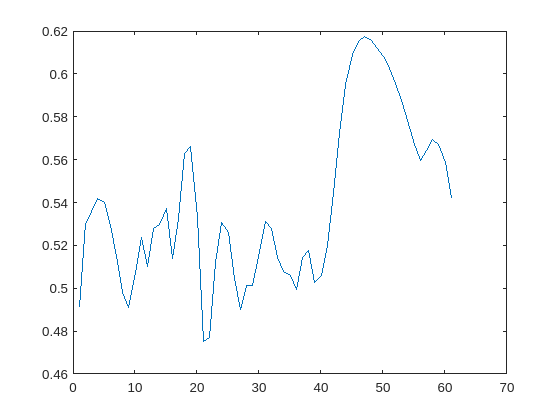

[bestScore,bestPos] = max(rezMaxMP{1}{1});

figure,plot(rezMaxMP{1}{1})

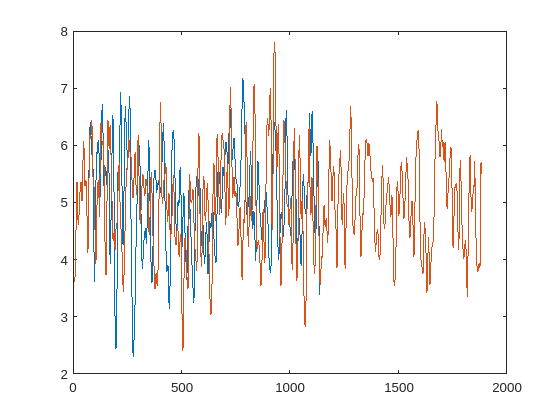



bestSF = sets.theory.stretchFactors(bestPos);
bestOr = rezMaxMP{1}{3}(bestPos);
bestPosA =  rezMaxMP{1}{2}(bestPos);
bestPosB =  rezMaxMP{1}{4}(bestPos);

bar = bGN{1}.rawBarcode;
if bestOr==2
    bar = fliplr(bar);
end

bar2 = bGN{2}.rawBarcode;


figure,plot(bestPosB-bestPosA+1:bestPosB-bestPosA+1+length(bar)-1,bar)
hold on
plot(bar2)